# determination of moments of inertia determined with data (.mpr) from Autocad

## Data from .mpr files

% mass of the rocket
mass = [1312001487.1908/2895861058.8942*4615
    1391194465.7760/2895861058.8942*4615
    1470387444.3611/2895861058.8942*4615
    1549580422.9463/2895861058.8942*4615
    1628773401.5315/2895861058.8942*4615
    1707966380.1166/2895861058.8942*4615
    1787159358.7018/2895861058.8942*4615
    1866352337.2870/2895861058.8942*4615
    1945545315.8721/2895861058.8942*4615
    2024738294.4573/2895861058.8942*4615
    2103931273.0425/2895861058.8942*4615
    2183124251.6276/2895861058.8942*4615
    2262317230.2128/2895861058.8942*4615
    2341510208.7980/2895861058.8942*4615
    2420703187.3831/2895861058.8942*4615
    2499896165.9683/2895861058.8942*4615
    2579089144.5535/2895861058.8942*4615
    2658282123.1386/2895861058.8942*4615
    2737475101.7238/2895861058.8942*4615
    2816668080.3090/2895861058.8942*4615
    2895861058.8942/2895861058.8942*4615 ]; 

% solid volume
V = [1312001487.1908  
    1391194465.7760 
    1470387444.3611 
    1549580422.9463 
    1628773401.5315 
    1707966380.1166 
    1787159358.7018
    1866352337.2870 
    1945545315.8721
    2024738294.4573
    2103931273.0425
    2183124251.6276  
    2262317230.2128
    2341510208.7980 
    2420703187.3831
    2499896165.9683
    2579089144.5535
    2658282123.1386 
    2737475101.7238
    2816668080.3090
    2895861058.8942 ]; 

% Center of Gravity [mm]
CG = [2810.7476 
    2875.9405 
    2941.2203 
    3006.5737 
    3071.9900 
    3137.4604 
    3202.9778
    3268.5361
    3334.1304
    3399.7564
    3465.4105
    3531.0898
    3596.7915 
    3662.5134 
    3728.2535 
    3794.0100 
    3859.7815
    3925.5666
    3991.3642
    4057.1731
    4122.9925 ];  

% moments of inertia [I_x I_y I_z]
M_bezw = [1.0009E+14 2661071015412923 2661071018604918
    1.0765E+14 2762923872394703 2762923875586698 
    1.1522E+14 2876895198158699 2876895201350695 
    1.2278E+14 3003675169911807 3003675173103802 
    1.3034E+14 3143953916633058 3143953919825051 
    1.3790E+14 3298421530254443 3298421533446437 
    1.4546E+14 3467768073869122 3467768077061116 
    1.5302E+14 3652683587849863 3652683591041859 
    1.6059E+14 3853858094473163 3853858097665158 
    1.6815E+14 4071981601458265 4071981604650260 
    1.7571E+14 4307744104706791 4307744107898786 
    1.8327E+14 4561835590446237 4561835593638231 
    1.9083E+14 4834946036923169 4834946040115163 
    1.9839E+14 5127765415752858 5127765418944854 
    2.0596E+14 5440983693004008 5440983696196001 
    2.1352E+14 5775290830077207 5775290833269201 
    2.2108E+14 6131376784421738 6131376787613735 
    2.2864E+14 6509931510124066 6509931513316063 
    2.3620E+14 6911644958394299 6911644961586294 
    2.4377E+14 7337207077970520 7337207081162515 
    2.5133E+14 7787307815456737 7787307818648729 ];


## Calculation of mass-inertia parameters

% percent of rocket fuel
fuel = [0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]; % [%]

% calculate mass of the rocket
% mass of rocket with 100% fuel - 4615 kg
% mass of rocket fuel - 2920 kg
p = polyfit([0 100],[4615-2920  4615],1);
mass_obl = p(1).*fuel + p(2); 

% calculate Autocad factor which provide the ability to calculate real parameters
WSP = mass_obl'./V./1e6;

% calculate real moments of inertia
M_bezw = M_bezw.*WSP;


## Plotting results

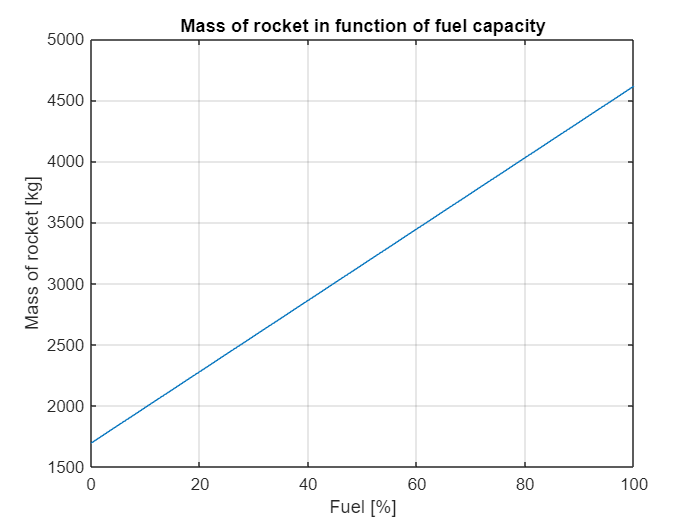


% ploting Mass of rocket in function of fuel capacity
figure
plot(fuel,mass_obl) 
title('Mass of rocket in function of fuel capacity')
xlabel('Fuel [%]'); ylabel('Mass of rocket [kg]')
grid on

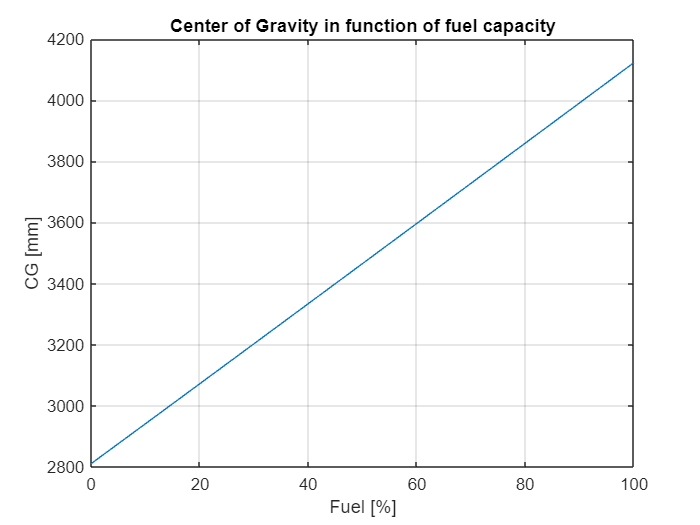


% ploting center of gravity in function of fuel capacity
figure
plot(fuel,CG)
title('Center of Gravity in function of fuel capacity')
xlabel('Fuel [%]'); ylabel('CG [mm]')
grid on

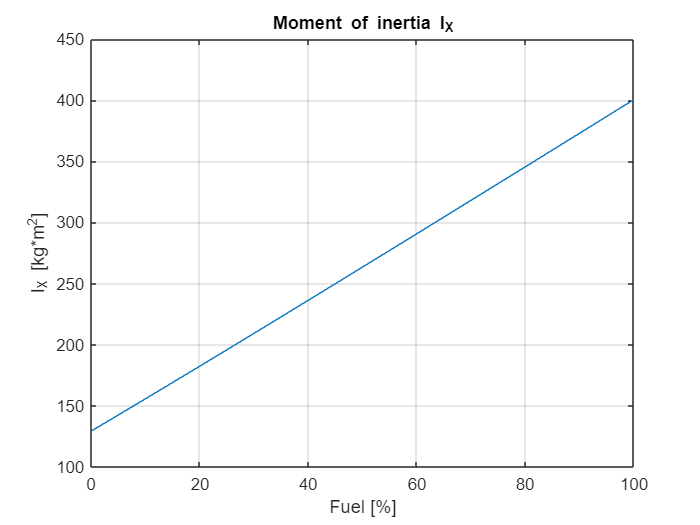


%ploting moment of inertia Ix
figure
plot(fuel,M_bezw(:,1))
title('Moment of inertia I_X')
xlabel('Fuel [%]'); ylabel('I_X [kg*m^2]')
grid on

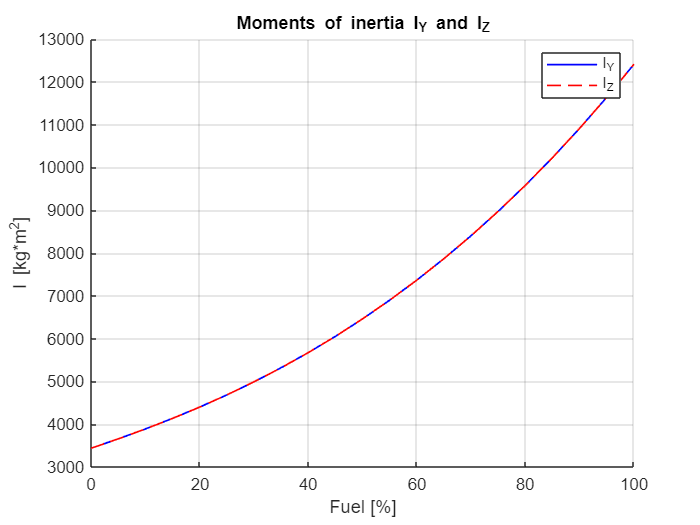


%ploting moments of inertia Iy and Iz 
figure
hold on
plot(fuel,M_bezw(:,2),'b',LineWidth=1)
plot(fuel,M_bezw(:,3),'r--',LineWidth=1)
hold off
title('Moments of inertia I_Y and I_Z')
xlabel('Fuel [%]'); ylabel('I [kg*m^2]')
grid on
legend('I_Y','I_Z')